## Introduction to vectors and vectors fields

a=[1,2,3]

a =      1     2     3


b=[-5,-3,-1]

b =     -5    -3    -1


c=[3,0,-3]

c =      3     0    -3


vector operations

a+b

ans =     -4    -1     2


5*c

ans =     15     0   -15


dot(a,b)

ans = -14

cross(a,b)

ans =      7   -14     7


cross(b,a)

ans =     -7    14    -7


Magnitude of scalar product of a and b

lengthhofa=sqrt(dot(a,b))

lengthhofa = 0.0000 + 3.7417i

    OR

norm(dot(a,b))

ans = 14

norm(a)

ans = 3.7417

dot(b,a)

ans = -14

M=sqrt(dot(b,a))

M = 0.0000 + 3.7417i

#### Angle between two vectors a and b

#### (angle will be in radians/degrees)

Angle =acos((dot(a,b))/(norm(a)*norm(b))) %in radians

Angle = 2.2555

Angle=acosd((dot(a,b))/(norm(a)*norm(b))) % in degrees

Angle = 129.2315

#### Plot of vector fields

 i) $F\left(x,y\right)=\frac{\left(\mathrm{yi}-\mathrm{xj}\right)}{\sqrt{x^2 +y^2 }}$     % in 2D

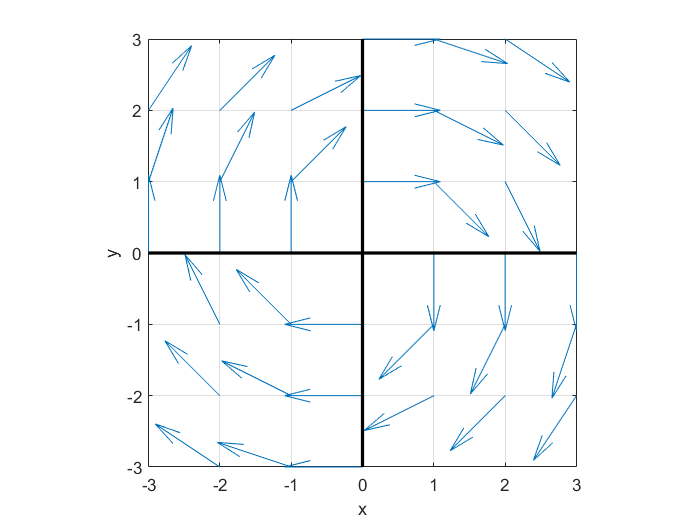

[x, y]= meshgrid(-3:3,-3:3);
u=y./sqrt(x.^2+y.^2); v=-x./sqrt(x.^2+y.^2);
figure;
quiver(x,y,u,v)
hold on
grid on
plot([0 0],[-3 3],'k','LineWidth',2)
plot([-3 3],[0 0],'k','LineWidth',2)
axis equal, axis([-3 3 -3 3])
xlabel('x')
ylabel('y')

$\left.\mathrm{ii}\right)\;F=\textrm{xi}+\textrm{yj}+\textrm{zk}$ % in 3D

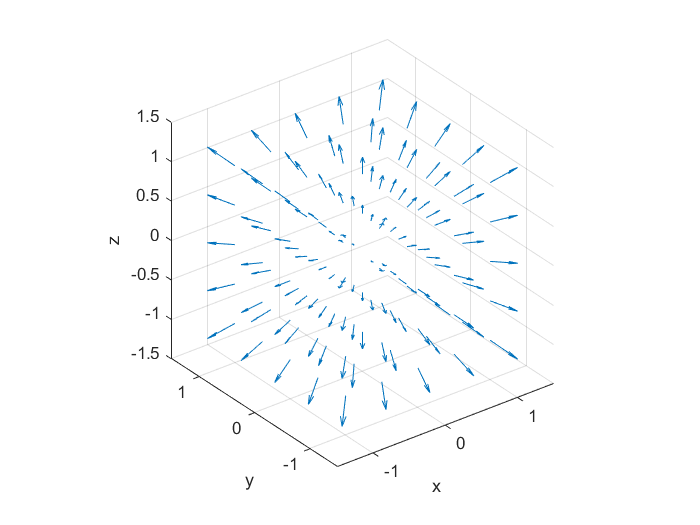

[x,y,z]=meshgrid(-1:0.5:1,-1:0.5:1,-1:0.5:1);
u=x;v=y;w=z;
figure
quiver3(x,y,z,u,v,w)
hold on
grid on
axis equal
axis([-1.5 1.5 -1.5 1.5 -1.5 1.5])
xlabel('x')
ylabel('y'), zlabel('z')

#### Finding the gradient at a point

syms x y z real
f=80/(1+x^2+2*y^2+3*z^2)
p=sym([1 1 -2])
grad_f=gradient(f, [x y z])'
grad_f_p=subs(grad_f, [x y z],p)

#### Plot of gradient field

####   
$$f=\frac{1}{2}\left(x^2 +y^2 \right)$$


syms x y
f=(1/2)*(x^2-y^2)

$$f = \frac{x^{2}}{2}-\frac{y^{2}}{2}$$

gradf=gradient(f,[x,y])'

$$gradf = \left(\begin{array}{cc} \bar{x} & -\bar{y} \end{array}\right)$$

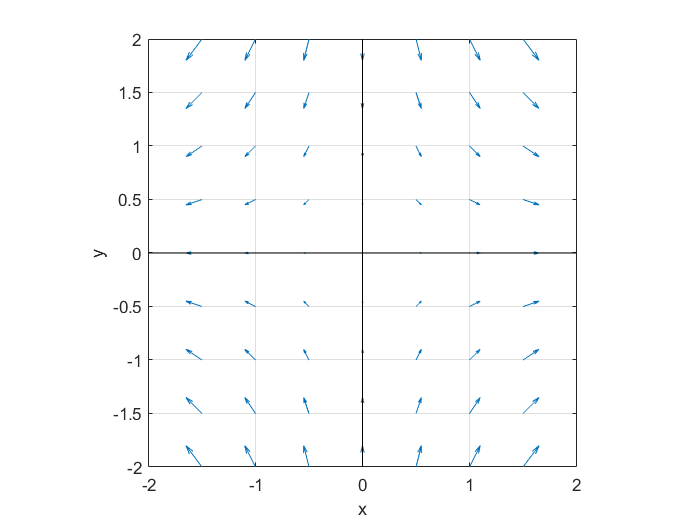

[x,y]=meshgrid([-2:0.5:2,-2:0.5:2]);
u=x; v=-y;
figure
quiver(x, y, u, v)
hold on 
grid on
plot([0 0],[-3 3],'k')
plot([-3 3],[0 0],'k')
axis equal
axis([-2  2 -2 2]),xlabel('x')
ylabel('y')

#### Plot gradient vector field together with contour map of f and how they are related to each other?


$$\mathrm{f}{\left(\mathrm{x},\mathrm{y}\right)}={\mathrm{x}}^2 +{\mathrm{y}}^2$$


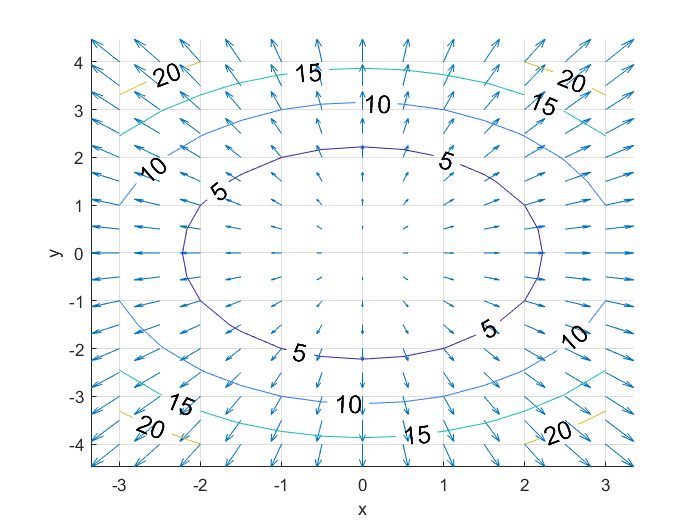

[x,y]=meshgrid(-3:0.5:3,-4:0.5:4);
f=x.^2+y.^2;
figure
hold on
grid on
[u,v]=gradient(f);
quiver(x,y,u,v)
[c,n]=contour(x,y,f);
clabel(c,n,'FontSize',15)
xlabel('x')
ylabel('y')

#### Finding directional derivative in given direction

#### Suppose tha**t over a certa**in region of space the electrical potential V is given by $\mathrm{V}{\left(\mathrm{x},\mathrm{y},\mathrm{z}\right)}=5{\mathrm{x}}^2 -3\mathrm{x}\mathrm{y}+\mathrm{x}\mathrm{y}\mathrm{z}\mathrm{ }$(i) Find the rate of change of the potential at P(3,4,5) in the direction of the vector $a=\mathrm{i}+\mathrm{j}-\mathrm{k}$   (ii) In which direction does V change most rapidly at P?   (iii) What is the maximum rate of change at P?

syms x y z real
P=sym([3 4 5])

$$P = \left(\begin{array}{ccc} 3 & 4 & 5 \end{array}\right)$$

v=5*x^2-3*x*y+x*y*z

$$v = 5\,x^{2}-3\,x\,y+x\,y\,z$$

gradv=gradient(v,[x y z])'

$$gradv = \left(\begin{array}{ccc} 10\,x-3\,y+y\,z & x\,z-3\,x & x\,y \end{array}\right)$$

grad_pt=subs(gradv,[x y z],P)

$$grad\_pt = \left(\begin{array}{ccc} 38 & 6 & 12 \end{array}\right)$$

a=[1 1 -1]%given direction

a =      1     1    -1


n=a/norm(a)%unit vector in given direction

n =     0.5774    0.5774   -0.5774


DD=dot(grad_pt,n)

$$DD = \frac{32\,\sqrt{3}}{3}$$

direction_of_rapid_change=grad_pt

$$direction\_of\_rapid\_change = \left(\begin{array}{ccc} 38 & 6 & 12 \end{array}\right)$$

max_rate_of_change=norm(grad_pt)

$$max\_rate\_of\_change = \sqrt{1624}$$

#### Curl and divergence of vector fields

syms x y z
F=[y*cos(x*y),x*cos(x*y),-sin(z)]

$$F = \left(\begin{array}{ccc} y\,\cos\left(x\,y\right) & x\,\cos\left(x\,y\right) & -\sin\left(z\right) \end{array}\right)$$

p=sym([1 0 0])

$$p = \left(\begin{array}{ccc} 1 & 0 & 0 \end{array}\right)$$

curl_F=curl(F,[x y z])'

$$curl\_F = \left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$

curl_p=subs(curl_F,[x y z],p)

$$curl\_p = \left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$

div_F=divergence(F,[x y z])

$$div\_F = -\cos\left(z\right)-x^{2}\,\sin\left(x\,y\right)-y^{2}\,\sin\left(x\,y\right)$$

div_p=subs(div_F,[x y z],p)

$$div\_p = -1$$

f=potential(F,[x y z])

$$f = \sin\left(x\,y\right)+\cos\left(z\right)$$

#### Evaluate line integral  $\int_c y^2 dx+x dy$,  where (a)$C=C_1$  is the line segment from (-5,-3) to (0,2) and (b) $C=C_2$  is the arc  of the parabola $x=4-y^2$  from (-5,-3) to (0,2)

syms x y x1 y1 t real
F=[y^2 x], P=sym([-5,-3]), Q=sym([0,2])

$$F = \left(\begin{array}{cc} y^{2} & x \end{array}\right)$$

$$P = \left(\begin{array}{cc} -5 & -3 \end{array}\right)$$

$$Q = \left(\begin{array}{cc} 0 & 2 \end{array}\right)$$

% patr (a)
v=Q-P

$$v = \left(\begin{array}{cc} 5 & 5 \end{array}\right)$$

r1=P+t*v

$$r1 = \left(\begin{array}{cc} 5\,t-5 & 5\,t-3 \end{array}\right)$$

dr1=diff(r1,t)

$$dr1 = \left(\begin{array}{cc} 5 & 5 \end{array}\right)$$

eq1=r1==P

$$eq1 = \left(\begin{array}{cc} 5\,t-5=-5 & 5\,t-3=-3 \end{array}\right)$$

t1=solve(eq1,t)

$$t1 = 0$$

eq2=r1==Q

$$eq2 = \left(\begin{array}{cc} 5\,t-5=0 & 5\,t-3=2 \end{array}\right)$$

t2=solve(eq2,t)

$$t2 = 1$$

int1=dot(F,dr1)

$$int1 = 5\,y^{2}+5\,x$$

I1=subs(int1,[x y],r1)

$$I1 = 25\,t+5\,{\left(5\,t-3\right)}^{2}-25$$

lineint_1=int(I1,t,t1,t2)

$$lineint\_1 = -\frac{5}{6}$$

%For part (b)
y1=t,x1=4-y1^2, r2=[x1 y1]

$$y1 = t$$

$$x1 = 4-t^{2}$$

$$r2 = \left(\begin{array}{cc} 4-t^{2} & t \end{array}\right)$$

dr2=diff(r2,t)

$$dr2 = \left(\begin{array}{cc} -2\,t & 1 \end{array}\right)$$

eq3=r2==P

$$eq3 = \left(\begin{array}{cc} 4-t^{2}=-5 & t=-3 \end{array}\right)$$

t3=solve(eq3,t)

$$t3 = -3$$

eq4=r2==Q

$$eq4 = \left(\begin{array}{cc} 4-t^{2}=0 & t=2 \end{array}\right)$$

t4=solve(eq4,t)

$$t4 = 2$$

int2=dot(F,dr2)

$$int2 = x-2\,t\,y^{2}$$

I2=subs(int2, [x y], r2)

$$I2 = -2\,t^{3}-t^{2}+4$$

lineint_2=int(I2,t,t3,t4)

$$lineint\_2 = \frac{245}{6}$$

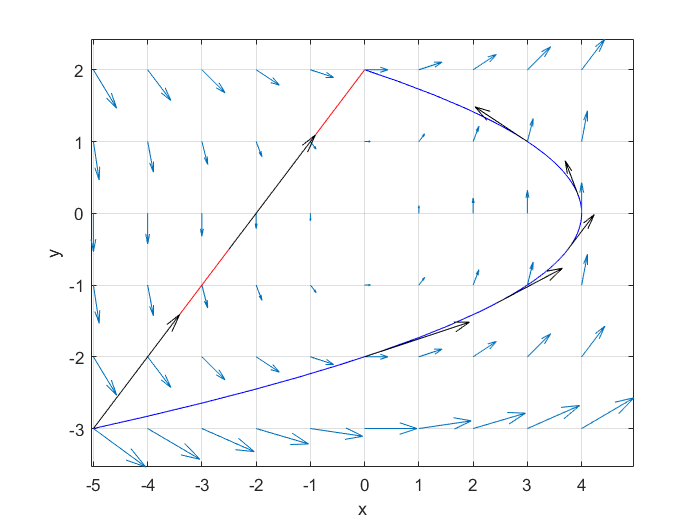


figure
fplot(r1(1),r1(2), [0 1],'r')
hold on 
grid on
fplot(r2(1),r2(2),[-3 2],'b')
%vector field
[x, y]=meshgrid(-5:4,-3:2);
u=y.^2; v=x;
quiver(x,y,u,v);
% tangent
% tangent vector
t=linspace(0,0.5,2);
x1=5*t-5; y1=5*t-3;
U=5*ones(size(x1)); V=5*ones(size(y1));
quiver(x1,y1,U,V,'k');
t1=linspace(-2,1,5);
x2=4-t1.^2; y2=t1;
U1=-2.*t1; V1=ones(size(y2));
quiver(x2,y2,U1,V1,'k');
xlabel('x'), ylabel('y')

**Application of line integrals**

#### i) Find the workdone by the force field $F=x^2 i-\mathrm{xyj}$ in moving a partical along the quater circle $r\left(t\right)=\mathrm{cost}\;i+\mathrm{sint}\;j,0\le t\le \frac{\pi }{2}$

syms f x y t r real
F=[x^2 -x*y], r=[cos(t) sin(t)]

$$F = \left(\begin{array}{cc} x^{2} & -x\,y \end{array}\right)$$

$$r = \left(\begin{array}{cc} \cos\left(t\right) & \sin\left(t\right) \end{array}\right)$$

F=subs(F,[x y],r)

$$F = \left(\begin{array}{cc} {\cos\left(t\right)}^{2} & -\cos\left(t\right)\,\sin\left(t\right) \end{array}\right)$$

dr=diff(r,t)

$$dr = \left(\begin{array}{cc} -\sin\left(t\right) & \cos\left(t\right) \end{array}\right)$$

int1=dot(F,dr)

$$int1 = -2\,{\cos\left(t\right)}^{2}\,\sin\left(t\right)$$

workdone=int(int1,t,0,pi/2)

$$workdone = -\frac{2}{3}$$

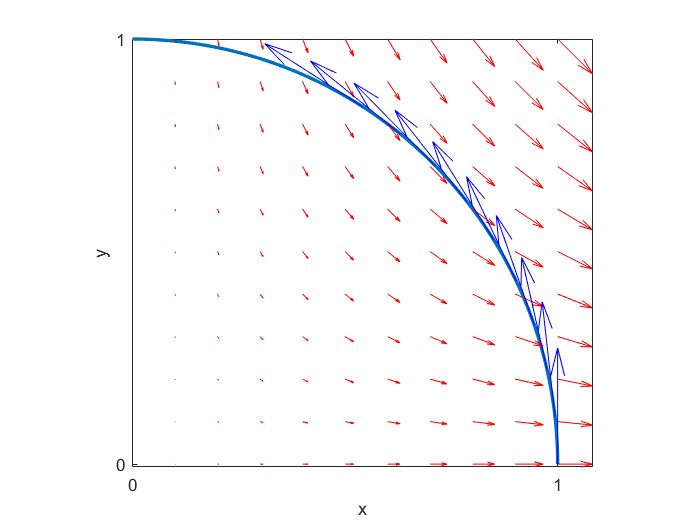


%path
figure
grid on
fplot(r(1),r(2), [0 pi/2], 'LineWidth',2);
hold on 

axis equal
xticks(0:3);yticks(0:4);xlabel('x');ylabel('y');
% vecor field
[x,y]=meshgrid(0:0.1:1, 0:0.1:1);

u=x.^2; v=-x.*y;
quiver(x,y,u,v,'r')
% tangent vector
t=linspace(0,1,10);
x=cos(t); y=sin(t);
U=-sin(t); V=cos(t);
quiver(x,y,U,V,'b')

#### ii) A 160-lb man carries a 25-lb can of paint up a helical staircase that encircles a silo with a radius of 20 ft. If the silo is 90 ft high and the man makes exactly three complete revolutions, how much work is done by the man against the gravity in climbing the top?

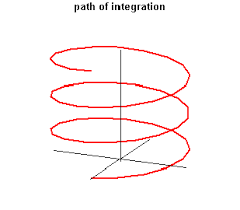

syms x y z t F r real
F=[0 0 185], r=[20*cos(t),20*sin(t),t*90/(6*pi)]

F =      0     0   185


$$r = \left(\begin{array}{ccc} 20\,\cos\left(t\right) & 20\,\sin\left(t\right) & \frac{15\,t}{\pi } \end{array}\right)$$


F=subs(F,[x y z],r)

$$F = \left(\begin{array}{ccc} 0 & 0 & 185 \end{array}\right)$$

dr=diff(r,t)

$$dr = \left(\begin{array}{ccc} -20\,\sin\left(t\right) & 20\,\cos\left(t\right) & \frac{15}{\pi } \end{array}\right)$$

int1=dot(F,dr)

$$int1 = \frac{2775}{\pi }$$

wk_dn=int(int1, t,0,6*pi)

$$wk\_dn = 16650$$

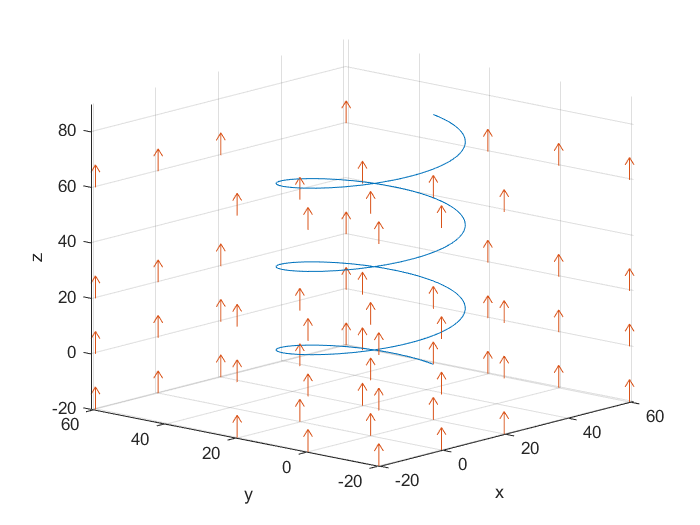

figure
fplot3(r(1),r(2),r(3), [0 6*pi])
hold on, grid on

view([-48.5 15.9])
% vector field
[x,y,z]=meshgrid([-20:20:20, -20:20:20,-20:40:80]);
u=zeros(size(x)); v=zeros(size(y)); w=ones(size(z));
quiver3(x,y,z,u,v,w)
xlabel('x'), ylabel('y'),zlabel('z')

**Greens Theorem**

 i) Use Greens theorem to evaluate the line integral along the given positively oriented curve  $\int_{\mathrm{c}} \left(\mathrm{y}+{\mathrm{e}}^{\sqrt{\mathrm{x}}} \right)\mathrm{d}\mathrm{x}+{\left(2\mathrm{x}+{\mathrm{c}\mathrm{o}\mathrm{s}\mathrm{y}}^2 \right)}\mathrm{d}\mathrm{y}$;  C is the boundary of the region enclosed by the parabolas   $\mathrm{y}={\mathrm{x}}^2$   and $\mathrm{x}={\mathrm{y}}^2$

syms x y t real
f=x^2, g=sqrt(x)

$$f = x^{2}$$

$$g = \sqrt{x}$$

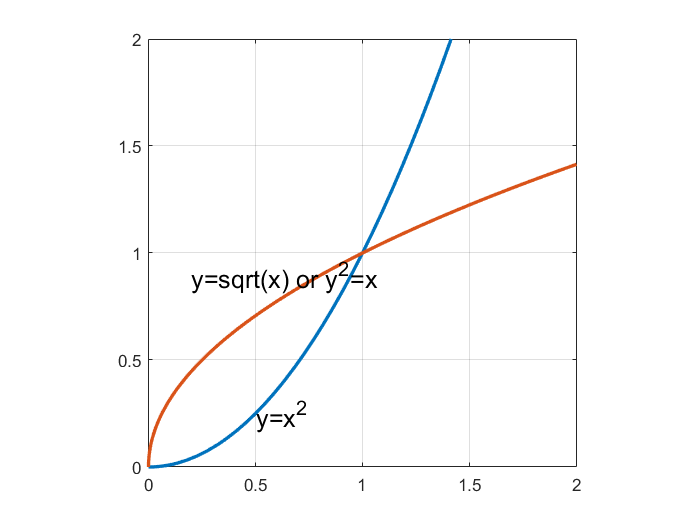

figure
fplot(f,[0 2],'LineWidth',2)
hold on 
grid on
fplot(g,[0 2],'LineWidth',2)
axis equal
axis([0 2 0 2])
xticks(0:0.5:2)
yticks(0:0.5:2)
text(0.5, 0.25, 'y=x^2', 'FontSize',15)
text(0.2,0.9, 'y=sqrt(x) or y^2=x','FontSize',15)
hold off

P=y+exp(sqrt(x)), Q=2*x+cos(y^2)

$$P = y+{\mathrm{e}}^{\sqrt{x}}$$

$$Q = 2\,x+\cos\left(y^{2}\right)$$

F=[P Q]

$$F = \left(\begin{array}{cc} y+{\mathrm{e}}^{\sqrt{x}} & 2\,x+\cos\left(y^{2}\right) \end{array}\right)$$

Qx=diff(Q,x)

$$Qx = 2$$

Py=diff(P,y)

$$Py = 1$$

int1=Qx-Py

$$int1 = 1$$

I=int(int(int1,y, x^2,sqrt(x)),x,0,1)

$$I = \frac{1}{3}$$

**Application of Greens Theorm **(to find area)

2.Using Green’s theorem, find the area of the region in the first quadrant bounded by the curves $\mathrm{y}=\mathrm{x},\mathrm{ }\mathrm{y}=\frac{1}{\mathrm{x}},\mathrm{ }\mathrm{y}=\frac{\mathrm{x}}{4}$

syms x y r1 t positive

y1=x, y2=1/x, y3=x/4

$$y1 = x$$

$$y2 = \frac{1}{x}$$

$$y3 = \frac{x}{4}$$

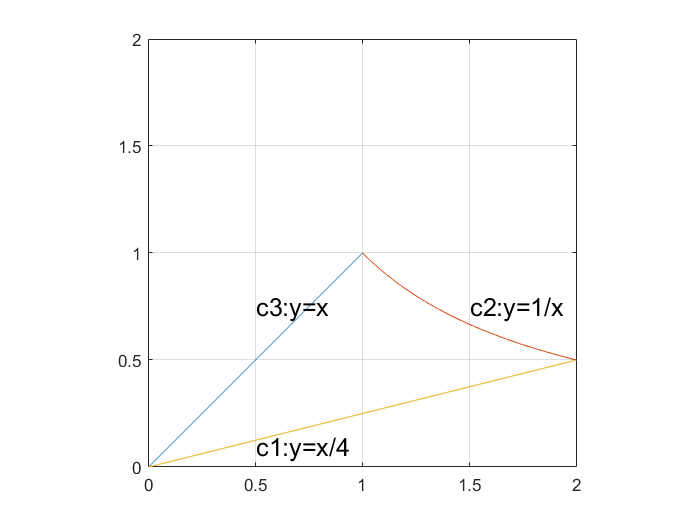

figure
fplot(y1,[0 1])
hold on
grid on
fplot(y2,[1 2])
fplot(y3, [0 2])
axis equal
axis([0 2 0 2])
xticks(0:0.5:2)
yticks(0:0.5:2)
text(0.5, 0.1, 'c1:y=x/4', 'FontSize',15)
text(0.5,0.75, 'c3:y=x','FontSize',15)
text(1.5,0.75, 'c2:y=1/x','FontSize',15)

F=[-y x];r1=[t t/4];

dr1=diff(r1,t)

$$dr1 = \left(\begin{array}{cc} 1 & \frac{1}{4} \end{array}\right)$$

int1=dot(F,dr1)

$$int1 = \frac{x}{4}-y$$

int1=subs(int1,[x y],r1)

$$int1 = 0$$

int_c1=int(int1,t,0,2)

$$int\_c1 = 0$$


r2=[t 1/t];
dr2=diff(r2,t)

$$dr2 = \left(\begin{array}{cc} 1 & -\frac{1}{t^{2}} \end{array}\right)$$

int2=dot(F,dr2)

$$int2 = -y-\frac{x}{t^{2}}$$

int2=subs(int2,[x y],r2)

$$int2 = -\frac{2}{t}$$

int_c2=int(int2,t,2,1)

$$int\_c2 = \log\left(4\right)$$



r3=[t t];

dr3=diff(r3,t)

$$dr3 = \left(\begin{array}{cc} 1 & 1 \end{array}\right)$$

int3=dot(F,dr3)

$$int3 = x-y$$

int3=subs(int3,[x y],r3)

$$int3 = 0$$

int_c3=int(int3,t,1,0)

$$int\_c3 = 0$$

I=int_c1+int_c2+int_c3

$$I = \log\left(4\right)$$

#### iii) Find the flux of $F=\mathrm{sin}\left(\mathrm{xyz}\right)i+x^2 \mathrm{yj}+z^3 e^{\left(\frac{x}{5}\right)} k$ across the part of the cylinder $4y^2 +z^2 =4$ that lies above the xy-plane and between the planes x=-2 and x=2 with upward orientation.

syms x y z theta real
P=sin(x*y*z),Q=x^2*y,R=z^2*exp(x/5)

$$P = \sin\left(x\,y\,z\right)$$

$$Q = x^{2}\,y$$

$$R = z^{2}\,{\mathrm{e}}^{x/5}$$

F=[P Q R]

$$F = \left(\begin{array}{ccc} \sin\left(x\,y\,z\right) & x^{2}\,y & z^{2}\,{\mathrm{e}}^{x/5} \end{array}\right)$$


z=sqrt(4-4*y^2)

$$z = 2\,\sqrt{1-y^{2}}$$

zx=diff(z,x)

$$zx = 0$$

zy=diff(z,y)

$$zy = -\frac{2\,y}{\sqrt{1-y^{2}}}$$

int1=-P*zx-Q*zy+R

$$int1 = z^{2}\,{\mathrm{e}}^{x/5}+\frac{2\,x^{2}\,y^{2}}{\sqrt{1-y^{2}}}$$

n=subs(int1)

$$n = \frac{2\,x^{2}\,y^{2}}{\sqrt{1-y^{2}}}-{\mathrm{e}}^{x/5}\,\left(4\,y^{2}-4\right)$$

flux=int(int(n,y,-1,1),x,-2,2)

$$flux = \frac{16\,\pi }{3}+\frac{80\,{\mathrm{e}}^{-\frac{2}{5}}\,\left({\mathrm{e}}^{4/5}-1\right)}{3}$$

flux=double(flux)

flux = 38.6620

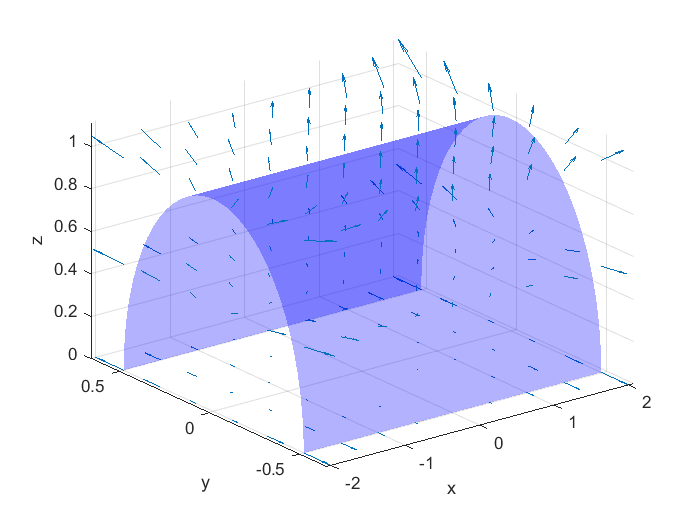


figure
fsurf(x, (1/2)*cos(theta), sin(theta),[0 pi -2 2],'b','EdgeColor','none' )
hold on
grid on
[x,y,z]=meshgrid(-2:0.5:2,-0.5:0.2:0.5,0:0.5:1);
u=sin(x.*y.*z);v=x.^2.*y;w=z.^2.*exp(x./5);
quiver3(x,y,z,u,v,w)
xlabel('x'),ylabel('y'),zlabel('z')

alpha 0.3

**Surface Integral**

#### A fluid with density 1500 and flows with velocity  $v=\textrm{yi}+\textrm{j}+\textrm{zk}$. Find the rate of  flow outward through the paraboloid $z=9-\left(\frac{1}{4}\right)\left(x^2 +y^2 \right),{\;x}^2 +y^2 \le 36$.

syms x y z r theta real
rho=1200

rho = 1200

v=[y 1 z]

$$v = \left(\begin{array}{ccc} y & 1 & z \end{array}\right)$$

F=rho*v

$$F = \left(\begin{array}{ccc} 1200\,y & 1200 & 1200\,z \end{array}\right)$$

z=9-(1/4)*(x^2+y^2)

$$z = -\frac{x^{2}}{4}-\frac{y^{2}}{4}+9$$

zx=diff(z,x),zy=diff(z,y)

$$zx = -\frac{x}{2}$$

$$zy = -\frac{y}{2}$$

int1=-F(1)*zx-F(2)*zy+F(3)

$$int1 = 600\,y+1200\,z+600\,x\,y$$

n=subs(int1)

$$n = -300\,x^{2}+600\,x\,y-300\,y^{2}+600\,y+10800$$

s=sqrt(36-x^2)

$$s = \sqrt{36-x^{2}}$$

rate_of_flow=int(int(n,y,-s,s),x,-6,6)

$$rate\_of\_flow = 194400\,\pi$$

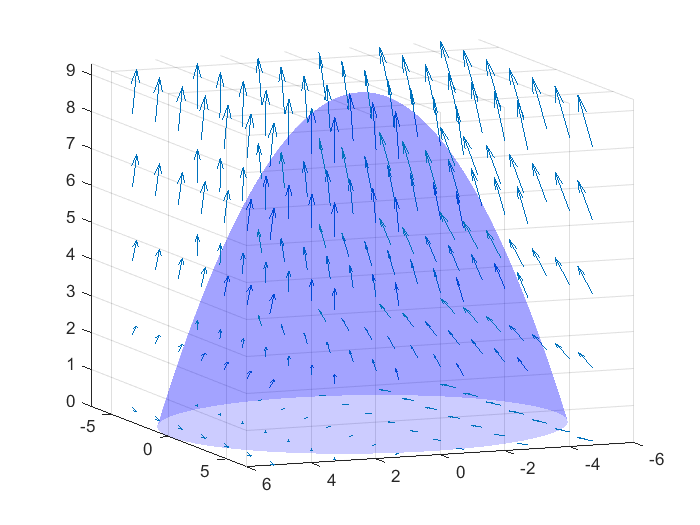

figure
fsurf(r*cos(theta),r*sin(theta),9-(1/4)*r^2,[0 6 0 2*pi],'b','EdgeColor','none')
hold on 
grid on
[x,y,z]=meshgrid(-6:2:6,-5:2:5,0:2:8);
u=1200*y; v=1200*ones(size(y)); w=1200*z;
quiver3(x,y,z,u,v,w)

view([-68.05 -10.82])

alpha 0.2

**Divergence theorem**

#### i) Use divergence theorem to calculate the flux of $F=3{\mathrm{xy}}^2 i+{\mathrm{xe}}^z j+z^3 k$ across surface S of the solid bounded by the cylinder  $y^2 +z^2 =1$ and the planes x=-1 and x=2 with upward orientation.

syms x y z r theta  real
F=[3*x*y^2 x*exp(z) z^3]

$$F = \left(\begin{array}{ccc} 3\,x\,y^{2} & x\,{\mathrm{e}}^{z} & z^{3} \end{array}\right)$$

F1=divergence(F,[x y z])

$$F1 = 3\,y^{2}+3\,z^{2}$$

x=x, y=r*cos(theta), z= r*sin(theta)

$$x = x$$

$$y = r\,\cos\left(\theta \right)$$

$$z = r\,\sin\left(\theta \right)$$

F1=simplify(subs(F1))

$$F1 = 3\,r^{2}$$

M=jacobian([x y z],[x r theta])

$$M = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\theta \right) & -r\,\sin\left(\theta \right)\\ 0 & \sin\left(\theta \right) & r\,\cos\left(\theta \right) \end{array}\right)$$

J=simplify(det(M))

$$J = r$$

int1=F1*abs(J)

$$int1 = 3\,r^{2}\,\left|r\right|$$

I=int(int(int(int1,r,0,1),theta, 0, 2*pi),x,-1,2)

$$I = \frac{9\,\pi }{2}$$

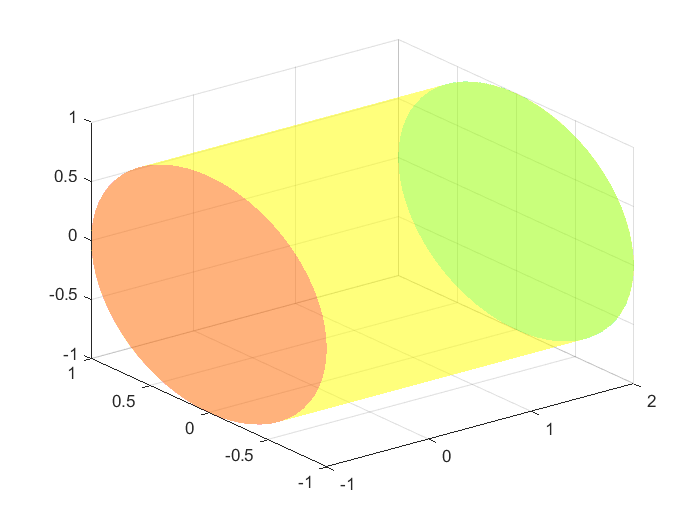

figure
fsurf(x, cos(theta), sin(theta),[0 2*pi -1 2],'y','EdgeColor','none' )
hold on
grid on
fsurf(-1,r*cos(theta), r*sin(theta),[0 1 0 2*pi],'r','Edgecolor','none' )
fsurf(2, r*cos(theta),r*sin(theta),[0 1 0 2*pi],'g','EdgeColor','none')

alpha 0.3

#### ii) A fluid has density 1500 and velocity field $v=-\mathrm{yi}+\mathrm{xj}+2\mathrm{zk}$. Find the rate of  flow outward through the sphere $x^2 +y^2 +z^2 =25$ 

syms x y z rho phi theta  real
density=1500

density = 1500

v=[-y x 2*z]

$$v = \left(\begin{array}{ccc} -y & x & 2\,z \end{array}\right)$$

F=density*v

$$F = \left(\begin{array}{ccc} -1500\,y & 1500\,x & 3000\,z \end{array}\right)$$

F1=divergence(F,[x y z])

$$F1 = 3000$$

x=rho*sin(phi)*cos(theta), y=rho*sin(phi)*sin(theta), z=rho*cos(phi)

$$x = \rho \,\cos\left(\theta \right)\,\sin\left(\phi \right)$$

$$y = \rho \,\sin\left(\phi \right)\,\sin\left(\theta \right)$$

$$z = \rho \,\cos\left(\phi \right)$$

F1=simplify(subs(F1))

$$F1 = 3000$$

M=jacobian([x y z],[rho phi theta])

$$M = \left(\begin{array}{ccc} \cos\left(\theta \right)\,\sin\left(\phi \right) & \rho \,\cos\left(\phi \right)\,\cos\left(\theta \right) & -\rho \,\sin\left(\phi \right)\,\sin\left(\theta \right)\\ \sin\left(\phi \right)\,\sin\left(\theta \right) & \rho \,\cos\left(\phi \right)\,\sin\left(\theta \right) & \rho \,\cos\left(\theta \right)\,\sin\left(\phi \right)\\ \cos\left(\phi \right) & -\rho \,\sin\left(\phi \right) & 0 \end{array}\right)$$

J=simplify(det(M))

$$J = \rho^{2}\,\sin\left(\phi \right)$$

int1=F1*abs(J)

$$int1 = 3000\,\rho^{2}\,\left|\sin\left(\phi \right)\right|$$

rate_of_flow=int(int(int(int1,rho,0,5),theta, 0, 2*pi),phi,0,pi)

$$rate\_of\_flow = 500000\,\pi$$

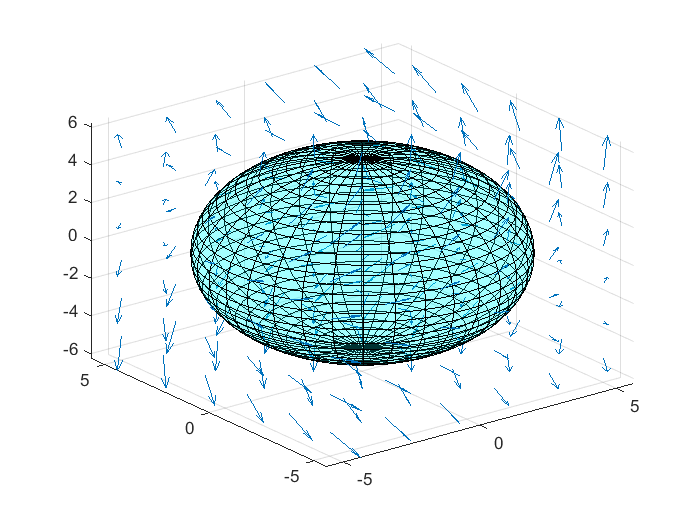

figure
fsurf(5*sin(phi)*cos(theta), 5*sin(phi)*sin(theta), 5*cos(phi),[0 pi 0 2*pi],'c')
hold on
grid on

[x, y, z]=meshgrid(-5:2:5,-5:2:5,-5:2:5);
u=-1500.*y; v=1500.*x; w=3000.*z;
quiver3(x,y,z,u,v,w);



alpha 0.2

iii) The temperature at the point (x,y,z) in a substance with conductivity K=6.5 is $u=2y^2 +2z^2$. Find the rate of heat flow inward across the cylindrical surface $y^2 +z^2 =6,\;0\le x\le 4$

syms x y z real
u=2*y^2+2*z^2

$$u = 2\,y^{2}+2\,z^{2}$$

gradu=gradient(u,[x,y,z])'

$$gradu = \left(\begin{array}{ccc} 0 & 4\,y & 4\,z \end{array}\right)$$

F=6.5*gradu

$$F = \left(\begin{array}{ccc} 0 & 26\,y & 26\,z \end{array}\right)$$

F1=divergence(F,[x, y, z])

$$F1 = 52$$

x=x,y=r*cos(theta), z=r*sin(theta)

$$x = x$$

$$y = r\,\cos\left(\theta \right)$$

$$z = r\,\sin\left(\theta \right)$$

F1=simplify(subs(F1))

$$F1 = 52$$

M=jacobian([x y z],[x r theta])

$$M = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\theta \right) & -r\,\sin\left(\theta \right)\\ 0 & \sin\left(\theta \right) & r\,\cos\left(\theta \right) \end{array}\right)$$

J=simplify(det(M))

$$J = r$$

int1=F1*abs(J)

$$int1 = 52\,\left|r\right|$$

heat_flow=int(int(int(int1,r,0,sqrt(6)),theta, 0, 2*pi),x,0,4)

$$heat\_flow = 1248\,\pi$$

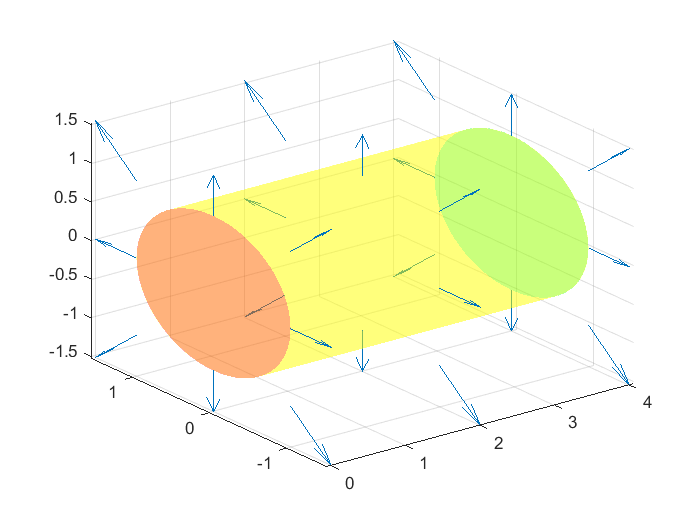

figure
fsurf(x, cos(theta), sin(theta),[0 2*pi 0 4],'y','EdgeColor','none' )
hold on
grid on
fsurf(0, r*cos(theta), r*sin(theta),[0 1 0 2*pi],'r','Edgecolor','none' )
fsurf(4, r*cos(theta),r*sin(theta),[0 1 0 2*pi],'g','EdgeColor','none')
[x,y,z]=meshgrid(0:2:4,-1:1,-1:1);
u=zeros(size(x)); v=2*y; w=2*z;
quiver3(x,y,z,u,v,w)

alpha 0.3

** Stokes Theorem**

 i) Use Stokes theorem to evaluate susface integral 

F=yzi+xzj+xyk ; S is surface of paraboloid $z=9-x^2 -y^2$ that lies above the plane z=5

syms x y z  r  t real
F=[y*z x*z x*y]

$$F = \left(\begin{array}{ccc} y\,z & x\,z & x\,y \end{array}\right)$$

R=[2*cos(t),2*sin(t),5]

$$R = \left(\begin{array}{ccc} 2\,\cos\left(t\right) & 2\,\sin\left(t\right) & 5 \end{array}\right)$$

dR=diff(R,t)

$$dR = \left(\begin{array}{ccc} -2\,\sin\left(t\right) & 2\,\cos\left(t\right) & 0 \end{array}\right)$$

FdR=dot(F,dR)

$$FdR = 2\,x\,z\,\cos\left(t\right)-2\,y\,z\,\sin\left(t\right)$$

I=subs(FdR,[x y z],R)

$$I = 20\,{\cos\left(t\right)}^{2}-20\,{\sin\left(t\right)}^{2}$$

line_int=int(I,t,0,2*pi)

$$line\_int = 0$$

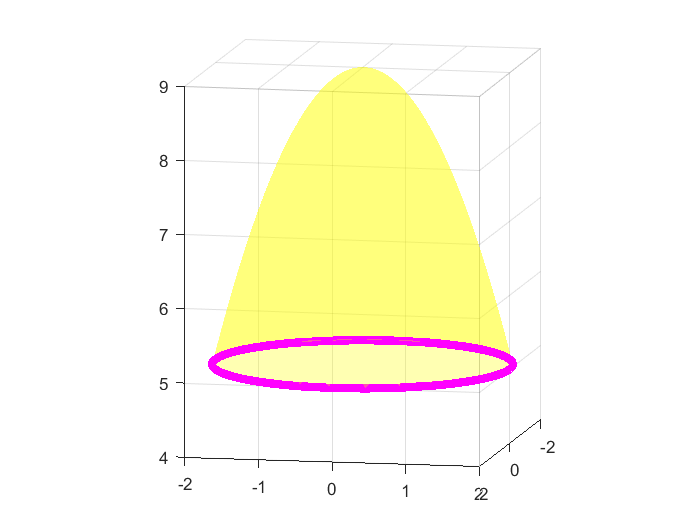


figure
fsurf(r*cos(t), r*sin(t), 9-r^2, [0 2 0 2*pi],'y', 'EdgeColor','none')
hold on, grid on
fplot3(2*cos(t),2*sin(t),sym(5),[0 2*pi],'m','LineWidth',5)
axis equal, axis([-2 2 -2 2 4 9])

view([-11.65 -9.25])

alpha 0.3

#### ii) Use Stokes theorem to evaluate line integral

#### $F=e^{-x} i+e^x j+e^z \;k$, C is boundary of the part of the plane $2x+y+2z=2$ in the first octant.

syms x y z real
F=[exp(-x),exp(x),exp(z)]

$$F = \left(\begin{array}{ccc} {\mathrm{e}}^{-x} & {\mathrm{e}}^{x} & {\mathrm{e}}^{z} \end{array}\right)$$

F1=curl(F,[x y z])'

$$F1 = \left(\begin{array}{ccc} 0 & 0 & {\mathrm{e}}^{x} \end{array}\right)$$

y=2-2*x-2*z

$$y = 2-2\,z-2\,x$$

yx=diff(y,x)

$$yx = -2$$

yz=diff(y,z)

$$yz = -2$$

I=-F1(1)*yx-F1(3)*yz+F1(2)

$$I = 2\,{\mathrm{e}}^{x}$$

I=subs(I)

$$I = 2\,{\mathrm{e}}^{x}$$

surf_int=int(int(I, z, 0, 1-x),x, 0, 1)

$$surf\_int = 2\,\mathrm{e}-4$$

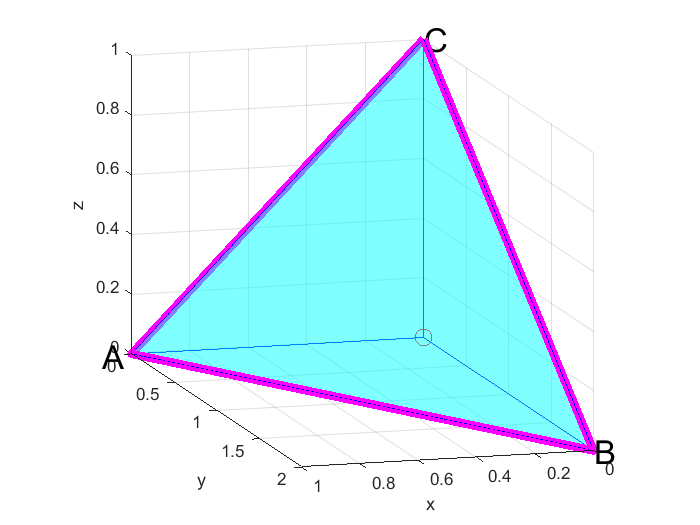


figure
X=[0 1 0 0];Y=[0 0 2 0]; Z=[1 0 0 1];
fill3(X,Y,Z,'c')
hold on, grid on
plot3(X,Y,Z, 'm','LineWidth',5)
plot3(0,0,0,'ro','MarkerSize',10)
plot3([0 1 0  0],[0 0 2 0],[0 0 0 0],'b')
plot3([0 0 0  0],[0 2 0 0],[0 0 1 0],'b')
plot3([0 1 0 0 ],[0 0 0 0],[1 0 0 1],'b')
plot3([0 1 0 0 ],[0 0 2 0],[1 0 0 1],'b')
text(1.1,0,0,'A','FontSize',20)
text(0,2,0,'B','FontSize',20)
text(0,0,1,'C','FontSize',20)
xlabel('x'),ylabel('y'),zlabel('z')
axis equal
axis([0 1 0 2 0 1])
view([163.786 11.160])

alpha 0.5